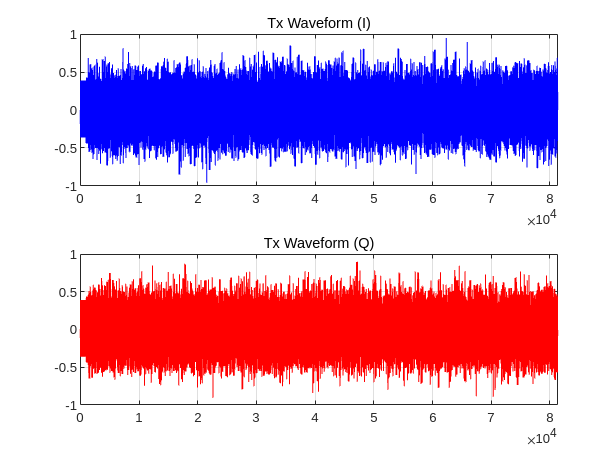

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% wl_example_siso_ofdm_txrx.m
% A detailed write-up of this example is available on the wiki:
% http://warpproject.org/trac/wiki/WARPLab/Examples/OFDM
%
% Copyright (c) 2015 Mango Communications - All Rights Reserved
% Distributed under the WARP License (http://warpproject.org/license)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear

% Params:
USE_WARPLAB_TXRX        = 0;           % Enable WARPLab-in-the-loop (otherwise sim-only)
WRITE_PNG_FILES         = 0;           % Enable writing plots to PNG
CHANNEL                 = 11;          % Channel to tune Tx and Rx radios

% Waveform params
N_OFDM_SYMS             = 500;         % Number of OFDM symbols
MOD_ORDER               = 16;           % Modulation order (2/4/16/64 = BSPK/QPSK/16-QAM/64-QAM)
TX_SCALE                = 1.0;          % Scale for Tx waveform ([0:1])

% OFDM params
SC_IND_PILOTS           = [8 22 44 58];                           % Pilot subcarrier indices
SC_IND_DATA             = [2:7 9:21 23:27 39:43 45:57 59:64];     % Data subcarrier indices
N_SC                    = 64;                                     % Number of subcarriers
CP_LEN                  = 16;                                     % Cyclic prefix length
N_DATA_SYMS             = N_OFDM_SYMS * length(SC_IND_DATA);      % Number of data symbols (one per data-bearing subcarrier per OFDM symbol)
INTERP_RATE             = 2;                                      % Interpolation rate (must be 2)

% Rx processing params
FFT_OFFSET                    = 4;           % Number of CP samples to use in FFT (on average)
LTS_CORR_THRESH               = 0.8;         % Normalized threshold for LTS correlation
DO_APPLY_CFO_CORRECTION       = 1;           % Enable CFO estimation/correction
DO_APPLY_PHASE_ERR_CORRECTION = 1;           % Enable Residual CFO estimation/correction
DO_APPLY_SFO_CORRECTION       = 1;           % Enable SFO estimation/correction

DECIMATE_RATE                 = INTERP_RATE;

% WARPLab experiment params
USE_AGC                 = true;        % Use the AGC if running on WARP hardware
MAX_TX_LEN              = 2^20;        % Maximum number of samples to use for this experiment
TRIGGER_OFFSET_TOL_NS   = 3000;        % Trigger time offset toleration between Tx and Rx that can be accomodated



if(USE_WARPLAB_TXRX)

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Set up the WARPLab experiment
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    NUMNODES = 2;

    % Create a vector of node objects
    nodes   = wl_initNodes(NUMNODES);
    node_tx = nodes(1);
    node_rx = nodes(2);

    % Create a UDP broadcast trigger and tell each node to be ready for it
    eth_trig = wl_trigger_eth_udp_broadcast;
    wl_triggerManagerCmd(nodes, 'add_ethernet_trigger', [eth_trig]);

    % Read Trigger IDs into workspace
    trig_in_ids  = wl_getTriggerInputIDs(nodes(1));
    trig_out_ids = wl_getTriggerOutputIDs(nodes(1));

    % For both nodes, we will allow Ethernet to trigger the buffer baseband and the AGC
    wl_triggerManagerCmd(nodes, 'output_config_input_selection', [trig_out_ids.BASEBAND, trig_out_ids.AGC], [trig_in_ids.ETH_A]);

    % Set the trigger output delays.
    nodes.wl_triggerManagerCmd('output_config_delay', [trig_out_ids.BASEBAND], 0);
    nodes.wl_triggerManagerCmd('output_config_delay', [trig_out_ids.AGC], TRIGGER_OFFSET_TOL_NS);

    % Get IDs for the interfaces on the boards. 
    ifc_ids_TX = wl_getInterfaceIDs(node_tx);
    ifc_ids_RX = wl_getInterfaceIDs(node_rx);

    % Set up the TX / RX nodes and RF interfaces
    TX_RF     = ifc_ids_TX.RF_A;
    TX_RF_VEC = ifc_ids_TX.RF_A;
    TX_RF_ALL = ifc_ids_TX.RF_ALL;
    
    RX_RF     = ifc_ids_RX.RF_A;
    RX_RF_VEC = ifc_ids_RX.RF_A;
    RX_RF_ALL = ifc_ids_RX.RF_ALL;

    % Set up the interface for the experiment
    wl_interfaceCmd(node_tx, TX_RF_ALL, 'channel', 2.4, CHANNEL);
    wl_interfaceCmd(node_rx, RX_RF_ALL, 'channel', 2.4, CHANNEL);

    wl_interfaceCmd(node_tx, TX_RF_ALL, 'tx_gains', 3, 30);

    if(USE_AGC)
        wl_interfaceCmd(node_rx, RX_RF_ALL, 'rx_gain_mode', 'automatic');
        wl_basebandCmd(nodes, 'agc_target', -13);
    else
        wl_interfaceCmd(node_rx, RX_RF_ALL, 'rx_gain_mode', 'manual');
        RxGainRF = 2;                  % Rx RF Gain in [1:3]
        RxGainBB = 12;                 % Rx Baseband Gain in [0:31]
        wl_interfaceCmd(node_rx, RX_RF_ALL, 'rx_gains', RxGainRF, RxGainBB);
    end

    % Get parameters from the node
    SAMP_FREQ    = wl_basebandCmd(nodes(1), 'tx_buff_clk_freq');
    Ts           = 1/SAMP_FREQ;

    % We will read the transmitter's maximum I/Q buffer length
    % and assign that value to a temporary variable.
    %
    % NOTE:  We assume that the buffers sizes are the same for all interfaces

    maximum_buffer_len = min(MAX_TX_LEN, wl_basebandCmd(node_tx, TX_RF_VEC, 'tx_buff_max_num_samples'));
    example_mode_string = 'hw';
else
    % Use sane defaults for hardware-dependent params in sim-only version
    maximum_buffer_len = min(MAX_TX_LEN, 2^20);
    SAMP_FREQ           = 40e6;
    example_mode_string = 'sim';
end

%% Define a half-band 2x interpolation filter response
interp_filt2 = zeros(1,43);
interp_filt2([1 3 5 7 9 11 13 15 17 19 21]) = [12 -32 72 -140 252 -422 682 -1086 1778 -3284 10364];
interp_filt2([23 25 27 29 31 33 35 37 39 41 43]) = interp_filt2(fliplr([1 3 5 7 9 11 13 15 17 19 21]));
interp_filt2(22) = 16384;
interp_filt2 = interp_filt2./max(abs(interp_filt2));

% Define the preamble
% Note: The STS symbols in the preamble meet the requirements needed by the
% AGC core at the receiver. Details on the operation of the AGC are
% available on the wiki: http://warpproject.org/trac/wiki/WARPLab/AGC
sts_f = zeros(1,64);
sts_f(1:27) = [0 0 0 0 -1-1i 0 0 0 -1-1i 0 0 0 1+1i 0 0 0 1+1i 0 0 0 1+1i 0 0 0 1+1i 0 0];
sts_f(39:64) = [0 0 1+1i 0 0 0 -1-1i 0 0 0 1+1i 0 0 0 -1-1i 0 0 0 -1-1i 0 0 0 1+1i 0 0 0];
sts_t = ifft(sqrt(13/6).*sts_f, 64);
sts_t = sts_t(1:16);

% LTS for CFO and channel estimation
lts_f = [0 1 -1 -1 1 1 -1 1 -1 1 -1 -1 -1 -1 -1 1 1 -1 -1 1 -1 1 -1 1 1 1 1 0 0 0 0 0 0 0 0 0 0 0 1 1 -1 -1 1 1 -1 1 -1 1 1 1 1 1 1 -1 -1 1 1 -1 1 -1 1 1 1 1];
lts_t = ifft(lts_f, 64);

% Use 30 copies of the 16-sample STS for extra AGC settling margin
preamble = [repmat(sts_t, 1, 30)  lts_t(33:64) lts_t lts_t];

% Sanity check variables that affect the number of Tx samples
num_samps_needed = ceil((TRIGGER_OFFSET_TOL_NS*1e-9) / (1/SAMP_FREQ)) + ...
                    INTERP_RATE*((N_OFDM_SYMS * (N_SC + CP_LEN)) + length(preamble) +  ceil(length(interp_filt2)/2));

                                
if(num_samps_needed > maximum_buffer_len)
    fprintf('Too many OFDM symbols for TX_NUM_SAMPS!\n');
    fprintf('Raise MAX_TX_LEN to %d, or \n', num_samps_needed);
    fprintf('Reduce N_OFDM_SYMS to %d\n', floor(((maximum_buffer_len - ceil((TRIGGER_OFFSET_TOL_NS*1e-9) / (1/SAMP_FREQ)))/INTERP_RATE - (length(preamble) +  ceil(length(interp_filt2)/2)))/(N_SC + CP_LEN)));
    return;
end

%% Generate a payload of random integers
tx_data = randi(MOD_ORDER, 1, N_DATA_SYMS) - 1;

% Functions for data -> complex symbol mapping (like qammod, avoids comm toolbox requirement)
% These anonymous functions implement the modulation mapping from IEEE 802.11-2012 Section 18.3.5.8
modvec_bpsk   =  (1/sqrt(2))  .* [-1 1];
modvec_16qam  =  (1/sqrt(10)) .* [-3 -1 +3 +1];
modvec_64qam  =  (1/sqrt(43)) .* [-7 -5 -1 -3 +7 +5 +1 +3];

mod_fcn_bpsk  = @(x) complex(modvec_bpsk(1+x),0);
mod_fcn_qpsk  = @(x) complex(modvec_bpsk(1+bitshift(x, -1)), modvec_bpsk(1+mod(x, 2)));
mod_fcn_16qam = @(x) complex(modvec_16qam(1+bitshift(x, -2)), modvec_16qam(1+mod(x,4)));
mod_fcn_64qam = @(x) complex(modvec_64qam(1+bitshift(x, -3)), modvec_64qam(1+mod(x,8)));

% Map the data values on to complex symbols
switch MOD_ORDER
    case 2         % BPSK
        tx_syms = arrayfun(mod_fcn_bpsk, tx_data);
    case 4         % QPSK
        tx_syms = arrayfun(mod_fcn_qpsk, tx_data);
    case 16        % 16-QAM
        tx_syms = arrayfun(mod_fcn_16qam, tx_data);
    case 64        % 64-QAM
        tx_syms = arrayfun(mod_fcn_64qam, tx_data);
    otherwise
        fprintf('Invalid MOD_ORDER (%d)!  Must be in [2, 4, 16, 64]\n', MOD_ORDER);
        return;
end

% Reshape the symbol vector to a matrix with one column per OFDM symbol
tx_syms_mat = reshape(tx_syms, length(SC_IND_DATA), N_OFDM_SYMS);

% Define the pilot tone values as BPSK symbols
pilots = [1 1 -1 1].';

% Repeat the pilots across all OFDM symbols
pilots_mat = repmat(pilots, 1, N_OFDM_SYMS);

%% IFFT

% Construct the IFFT input matrix
ifft_in_mat = zeros(N_SC, N_OFDM_SYMS);

% Insert the data and pilot values; other subcarriers will remain at 0
ifft_in_mat(SC_IND_DATA, :)   = tx_syms_mat;
ifft_in_mat(SC_IND_PILOTS, :) = pilots_mat;

%Perform the IFFT
tx_payload_mat = ifft(ifft_in_mat, N_SC, 1);

% Insert the cyclic prefix
if(CP_LEN > 0)
    tx_cp = tx_payload_mat((end-CP_LEN+1 : end), :);
    tx_payload_mat = [tx_cp; tx_payload_mat];
end

% Reshape to a vector
tx_payload_vec = reshape(tx_payload_mat, 1, numel(tx_payload_mat));

% Construct the full time-domain OFDM waveform
tx_vec = [preamble tx_payload_vec];

% Pad with zeros for transmission to deal with delay through the
% interpolation filter
tx_vec_padded = [tx_vec, zeros(1, ceil(length(interp_filt2)/2))];

%% Interpolate
% Zero pad then filter (same as interp or upfirdn without signal processing toolbox)
if( INTERP_RATE ~= 2)
   fprintf('Error: INTERP_RATE must equal 2\n'); 
   return;
end

tx_vec_2x = zeros(1, 2*numel(tx_vec_padded));
tx_vec_2x(1:2:end) = tx_vec_padded;
tx_vec_air = filter(interp_filt2, 1, tx_vec_2x);


% Scale the Tx vector to +/- 1
tx_vec_air = TX_SCALE .* tx_vec_air ./ max(abs(tx_vec_air));

TX_NUM_SAMPS = length(tx_vec_air);

if(USE_WARPLAB_TXRX)
    wl_basebandCmd(nodes, 'tx_delay', 0);
    wl_basebandCmd(nodes, 'tx_length', TX_NUM_SAMPS);                                                        % Number of samples to send
    wl_basebandCmd(nodes, 'rx_length', TX_NUM_SAMPS + ceil((TRIGGER_OFFSET_TOL_NS*1e-9) / (1/SAMP_FREQ)));   % Number of samples to receive
end


%% WARPLab Tx/Rx
if(USE_WARPLAB_TXRX)
    % Write the Tx waveform to the Tx node
    wl_basebandCmd(node_tx, TX_RF_VEC, 'write_IQ', tx_vec_air(:));

    % Enable the Tx and Rx radios
    wl_interfaceCmd(node_tx, TX_RF, 'tx_en');
    wl_interfaceCmd(node_rx, RX_RF, 'rx_en');

    % Enable the Tx and Rx buffers
    wl_basebandCmd(node_tx, TX_RF, 'tx_buff_en');
    wl_basebandCmd(node_rx, RX_RF, 'rx_buff_en');

    % Trigger the Tx/Rx cycle at both nodes
    eth_trig.send();

    % Retrieve the received waveform from the Rx node
    rx_vec_air = wl_basebandCmd(node_rx, RX_RF_VEC, 'read_IQ', 0, TX_NUM_SAMPS + (ceil((TRIGGER_OFFSET_TOL_NS*1e-9) / (1/SAMP_FREQ))));

    rx_vec_air = rx_vec_air(:).';

    % Disable the Tx/Rx radios and buffers
    wl_basebandCmd(node_tx, TX_RF_ALL, 'tx_rx_buff_dis');
    wl_basebandCmd(node_rx, RX_RF_ALL, 'tx_rx_buff_dis');
    
    wl_interfaceCmd(node_tx, TX_RF_ALL, 'tx_rx_dis');
    wl_interfaceCmd(node_rx, RX_RF_ALL, 'tx_rx_dis');
else
    % Sim-only mode: Apply wireless degradations here for sim (noise, fading, etc)

    % Perfect (ie. Rx=Tx):
    % rx_vec_air = tx_vec_air;

    % AWGN:
    rx_vec_air = [tx_vec_air, zeros(1,ceil((TRIGGER_OFFSET_TOL_NS*1e-9) / (1/SAMP_FREQ)))];
    rx_vec_air = rx_vec_air + 0*complex(randn(1,length(rx_vec_air)), randn(1,length(rx_vec_air)));

    % CFO:
    % rx_vec_air = tx_vec_air .* exp(-1i*2*pi*1e-4*[0:length(tx_vec_air)-1]);
end

%% Decimate
if( INTERP_RATE ~= 2)
   fprintf('Error: INTERP_RATE must equal 2\n'); 
   return;
end

raw_rx_dec = filter(interp_filt2, 1, rx_vec_air);
raw_rx_dec = raw_rx_dec(1:2:end);


%% Correlate for LTS

% Complex cross correlation of Rx waveform with time-domain LTS
lts_corr = abs(conv(conj(fliplr(lts_t)), sign(raw_rx_dec)));

% Skip early and late samples - avoids occasional false positives from pre-AGC samples
lts_corr = lts_corr(32:end-32);

% Find all correlation peaks
lts_peaks = find(lts_corr(1:800) > LTS_CORR_THRESH*max(lts_corr));

% Select best candidate correlation peak as LTS-payload boundary
[LTS1, LTS2] = meshgrid(lts_peaks,lts_peaks);
[lts_second_peak_index,y] = find(LTS2-LTS1 == length(lts_t));

% Stop if no valid correlation peak was found
if(isempty(lts_second_peak_index))
    fprintf('No LTS Correlation Peaks Found!\n');
    return;
end

% Set the sample indices of the payload symbols and preamble
% The "+32" corresponds to the 32-sample cyclic prefix on the preamble LTS
% The "-160" corresponds to the length of the preamble LTS (2.5 copies of 64-sample LTS)
payload_ind = lts_peaks(max(lts_second_peak_index)) + 32;
lts_ind = payload_ind-160;

if(DO_APPLY_CFO_CORRECTION)
    %Extract LTS (not yet CFO corrected)
    rx_lts = raw_rx_dec(lts_ind : lts_ind+159);
    rx_lts1 = rx_lts(-64+-FFT_OFFSET + [97:160]);
    rx_lts2 = rx_lts(-FFT_OFFSET + [97:160]);

    %Calculate coarse CFO est
    rx_cfo_est_lts = mean(unwrap(angle(rx_lts2 .* conj(rx_lts1))));
    rx_cfo_est_lts = rx_cfo_est_lts/(2*pi*64);
else
    rx_cfo_est_lts = 0;
end

% Apply CFO correction to raw Rx waveform
rx_cfo_corr_t = exp(-1i*2*pi*rx_cfo_est_lts*[0:length(raw_rx_dec)-1]);
rx_dec_cfo_corr = raw_rx_dec .* rx_cfo_corr_t;

% Re-extract LTS for channel estimate
rx_lts = rx_dec_cfo_corr(lts_ind : lts_ind+159);
rx_lts1 = rx_lts(-64+-FFT_OFFSET + [97:160]);
rx_lts2 = rx_lts(-FFT_OFFSET + [97:160]);

rx_lts1_f = fft(rx_lts1);
rx_lts2_f = fft(rx_lts2);

% Calculate channel estimate from average of 2 training symbols
rx_H_est = lts_f .* (rx_lts1_f + rx_lts2_f)/2;

%% Rx payload processing

% Extract the payload samples (integral number of OFDM symbols following preamble)
payload_vec = rx_dec_cfo_corr(payload_ind : payload_ind+N_OFDM_SYMS*(N_SC+CP_LEN)-1);
payload_mat = reshape(payload_vec, (N_SC+CP_LEN), N_OFDM_SYMS);

% Remove the cyclic prefix, keeping FFT_OFFSET samples of CP (on average)
payload_mat_noCP = payload_mat(CP_LEN-FFT_OFFSET+[1:N_SC], :);

% Take the FFT
syms_f_mat = fft(payload_mat_noCP, N_SC, 1);

% Equalize (zero-forcing, just divide by complex chan estimates)
syms_eq_mat = syms_f_mat ./ repmat(rx_H_est.', 1, N_OFDM_SYMS);

if DO_APPLY_SFO_CORRECTION
    % SFO manifests as a frequency-dependent phase whose slope increases
    % over time as the Tx and Rx sample streams drift apart from one
    % another. To correct for this effect, we calculate this phase slope at
    % each OFDM symbol using the pilot tones and use this slope to
    % interpolate a phase correction for each data-bearing subcarrier.

	% Extract the pilot tones and "equalize" them by their nominal Tx values
    pilots_f_mat = syms_eq_mat(SC_IND_PILOTS, :);
    pilots_f_mat_comp = pilots_f_mat.*pilots_mat;

	% Calculate the phases of every Rx pilot tone
    pilot_phases = unwrap(angle(fftshift(pilots_f_mat_comp,1)), [], 1);

	% Calculate slope of pilot tone phases vs frequency in each OFDM symbol
    pilot_spacing_mat = repmat(mod(diff(fftshift(SC_IND_PILOTS)),64).', 1, N_OFDM_SYMS);                        
	pilot_slope_mat = mean(diff(pilot_phases) ./ pilot_spacing_mat);

	% Calculate the SFO correction phases for each OFDM symbol
    pilot_phase_sfo_corr = fftshift((-32:31).' * pilot_slope_mat, 1);
    pilot_phase_corr = exp(-1i*(pilot_phase_sfo_corr));

    % Apply the pilot phase correction per symbol
    syms_eq_mat = syms_eq_mat .* pilot_phase_corr;
else
	% Define an empty SFO correction matrix (used by plotting code below)
    pilot_phase_sfo_corr = zeros(N_SC, N_OFDM_SYMS);
end


if DO_APPLY_PHASE_ERR_CORRECTION
    % Extract the pilots and calculate per-symbol phase error
    pilots_f_mat = syms_eq_mat(SC_IND_PILOTS, :);
    pilots_f_mat_comp = pilots_f_mat.*pilots_mat;
    pilot_phase_err = angle(mean(pilots_f_mat_comp));
else
	% Define an empty phase correction vector (used by plotting code below)
    pilot_phase_err = zeros(1, N_OFDM_SYMS);
end
pilot_phase_err_corr = repmat(pilot_phase_err, N_SC, 1);
pilot_phase_corr = exp(-1i*(pilot_phase_err_corr));

% Apply the pilot phase correction per symbol
syms_eq_pc_mat = syms_eq_mat .* pilot_phase_corr;
payload_syms_mat = syms_eq_pc_mat(SC_IND_DATA, :);

%% Demodulate
rx_syms = reshape(payload_syms_mat, 1, N_DATA_SYMS);

demod_fcn_bpsk = @(x) double(real(x)>0);
demod_fcn_qpsk = @(x) double(2*(real(x)>0) + 1*(imag(x)>0));
demod_fcn_16qam = @(x) (8*(real(x)>0)) + (4*(abs(real(x))<0.6325)) + (2*(imag(x)>0)) + (1*(abs(imag(x))<0.6325));
demod_fcn_64qam = @(x) (32*(real(x)>0)) + (16*(abs(real(x))<0.6172)) + (8*((abs(real(x))<(0.9258))&&((abs(real(x))>(0.3086))))) + (4*(imag(x)>0)) + (2*(abs(imag(x))<0.6172)) + (1*((abs(imag(x))<(0.9258))&&((abs(imag(x))>(0.3086)))));

switch(MOD_ORDER)
    case 2         % BPSK
        rx_data = arrayfun(demod_fcn_bpsk, rx_syms);
    case 4         % QPSK
        rx_data = arrayfun(demod_fcn_qpsk, rx_syms);
    case 16        % 16-QAM
        rx_data = arrayfun(demod_fcn_16qam, rx_syms);
    case 64        % 64-QAM
        rx_data = arrayfun(demod_fcn_64qam, rx_syms);
end

%% Plot Results
cf = 0;

% Tx signal
cf = cf + 1;
figure(cf); clf;

subplot(2,1,1);
plot(real(tx_vec_air), 'b');
axis([0 length(tx_vec_air) -TX_SCALE TX_SCALE])
grid on;
title('Tx Waveform (I)');

subplot(2,1,2);
plot(imag(tx_vec_air), 'r');
axis([0 length(tx_vec_air) -TX_SCALE TX_SCALE])
grid on;
title('Tx Waveform (Q)');

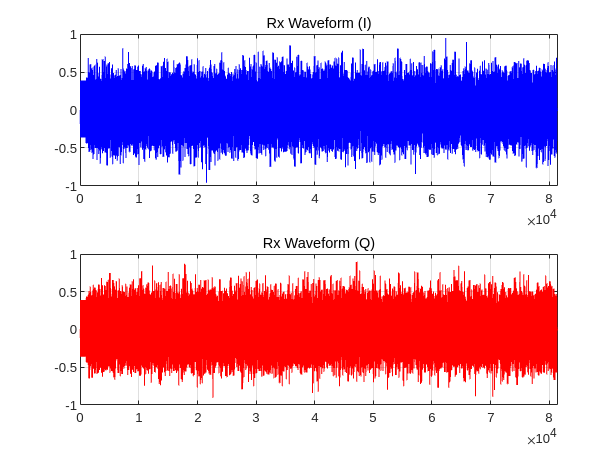


if(WRITE_PNG_FILES)
    print(gcf,sprintf('wl_ofdm_plots_%s_txIQ', example_mode_string), '-dpng', '-r96', '-painters')
end

% Rx signal
cf = cf + 1;
figure(cf); clf;
subplot(2,1,1);
plot(real(rx_vec_air), 'b');
axis([0 length(rx_vec_air) -TX_SCALE TX_SCALE])
grid on;
title('Rx Waveform (I)');

subplot(2,1,2);
plot(imag(rx_vec_air), 'r');
axis([0 length(rx_vec_air) -TX_SCALE TX_SCALE])
grid on;
title('Rx Waveform (Q)');


if(WRITE_PNG_FILES)
    print(gcf,sprintf('wl_ofdm_plots_%s_rxIQ', example_mode_string), '-dpng', '-r96', '-painters')
end

% Rx LTS correlation
cf = cf + 1;
figure(cf); clf;
lts_to_plot = lts_corr;
plot(lts_to_plot, '.-b', 'LineWidth', 1);
hold on;
grid on;
line([1 length(lts_to_plot)], LTS_CORR_THRESH*max(lts_to_plot)*[1 1], 'LineStyle', '--', 'Color', 'r', 'LineWidth', 2);
title('LTS Correlation and Threshold')
xlabel('Sample Index')
myAxis = axis();1

ans = 1

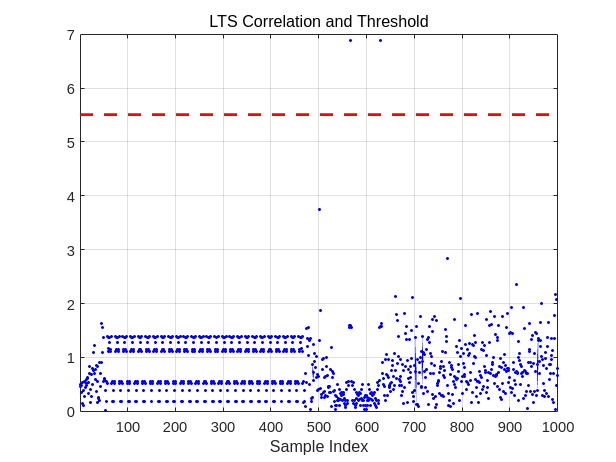

axis([1, 1000, myAxis(3), myAxis(4)])

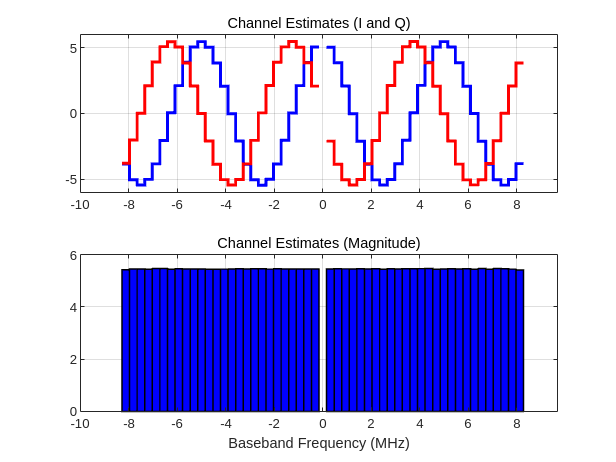


if(WRITE_PNG_FILES)
    print(gcf,sprintf('wl_ofdm_plots_%s_ltsCorr', example_mode_string), '-dpng', '-r96', '-painters')
end

% Channel Estimates
cf = cf + 1;

rx_H_est_plot = repmat(complex(NaN,NaN),1,length(rx_H_est));
rx_H_est_plot(SC_IND_DATA) = rx_H_est(SC_IND_DATA);
rx_H_est_plot(SC_IND_PILOTS) = rx_H_est(SC_IND_PILOTS);

x = (20/N_SC) * (-(N_SC/2):(N_SC/2 - 1));

figure(cf); clf;
subplot(2,1,1);
stairs(x - (20/(2*N_SC)), fftshift(real(rx_H_est_plot)), 'b', 'LineWidth', 2);
hold on
stairs(x - (20/(2*N_SC)), fftshift(imag(rx_H_est_plot)), 'r', 'LineWidth', 2);
hold off
axis([min(x) max(x) -1.1*max(abs(rx_H_est_plot)) 1.1*max(abs(rx_H_est_plot))])
grid on;
title('Channel Estimates (I and Q)')

subplot(2,1,2);
bh = bar(x, fftshift(abs(rx_H_est_plot)),1,'LineWidth', 1);
shading flat
set(bh,'FaceColor',[0 0 1])
axis([min(x) max(x) 0 1.1*max(abs(rx_H_est_plot))])
grid on;
title('Channel Estimates (Magnitude)')
xlabel('Baseband Frequency (MHz)')

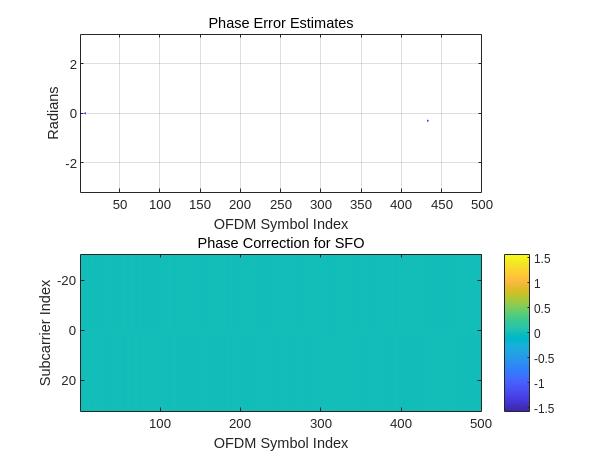


if(WRITE_PNG_FILES)
    print(gcf,sprintf('wl_ofdm_plots_%s_chanEst', example_mode_string), '-dpng', '-r96', '-painters')
end

%% Pilot phase error estimate
cf = cf + 1;
figure(cf); clf;
subplot(2,1,1)
plot(pilot_phase_err, 'b', 'LineWidth', 2);
title('Phase Error Estimates')
xlabel('OFDM Symbol Index')
ylabel('Radians')
axis([1 N_OFDM_SYMS -3.2 3.2])
grid on

h = colorbar;
set(h,'Visible','off');

subplot(2,1,2)
imagesc(1:N_OFDM_SYMS, (SC_IND_DATA - N_SC/2), fftshift(pilot_phase_sfo_corr,1))
xlabel('OFDM Symbol Index')
ylabel('Subcarrier Index')
title('Phase Correction for SFO')
colorbar
myAxis = caxis();
if(myAxis(2)-myAxis(1) < (pi))
   caxis([-pi/2 pi/2])
end

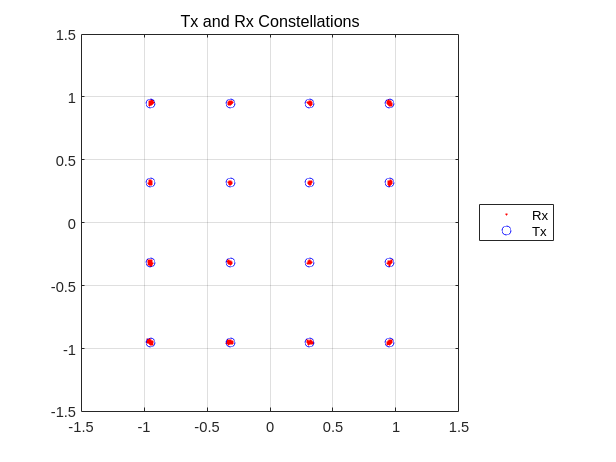



if(WRITE_PNG_FILES)
    print(gcf,sprintf('wl_ofdm_plots_%s_phaseError', example_mode_string), '-dpng', '-r96', '-painters')
end

%% Symbol constellation
cf = cf + 1;
figure(cf); clf;

plot(payload_syms_mat(:),'ro','MarkerSize',1);
axis square; axis(1.5*[-1 1 -1 1]);
grid on;
hold on;

plot(tx_syms_mat(:),'bo');
title('Tx and Rx Constellations')
legend('Rx','Tx','Location','EastOutside');

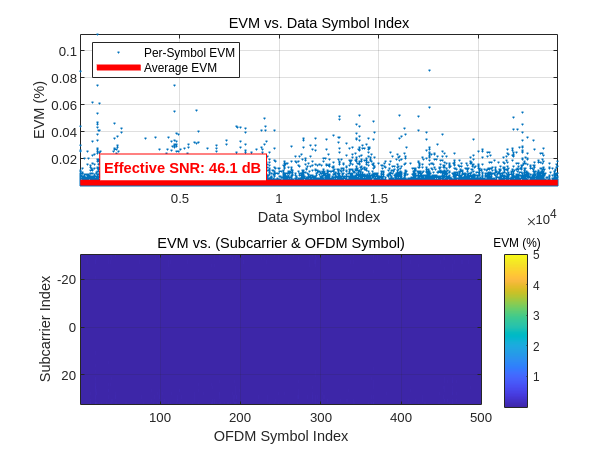


if(WRITE_PNG_FILES)
    print(gcf,sprintf('wl_ofdm_plots_%s_constellations', example_mode_string), '-dpng', '-r96', '-painters')
end


% EVM & SNR
cf = cf + 1;
figure(cf); clf;

evm_mat = abs(payload_syms_mat - tx_syms_mat).^2;
aevms = mean(evm_mat(:));
snr = 10*log10(1./aevms);

subplot(2,1,1)
plot(100*evm_mat(:),'o','MarkerSize',1)
axis tight
hold on
plot([1 length(evm_mat(:))], 100*[aevms, aevms],'r','LineWidth',4)
myAxis = axis;
h = text(round(.05*length(evm_mat(:))), 100*aevms+ .1*(myAxis(4)-myAxis(3)), sprintf('Effective SNR: %.1f dB', snr));
set(h,'Color',[1 0 0])
set(h,'FontWeight','bold')
set(h,'FontSize',10)
set(h,'EdgeColor',[1 0 0])
set(h,'BackgroundColor',[1 1 1])
hold off
xlabel('Data Symbol Index')
ylabel('EVM (%)');
legend('Per-Symbol EVM','Average EVM','Location','NorthWest');
title('EVM vs. Data Symbol Index')
grid on

subplot(2,1,2)
imagesc(1:N_OFDM_SYMS, (SC_IND_DATA - N_SC/2), 100*fftshift(evm_mat,1))

grid on
xlabel('OFDM Symbol Index')
ylabel('Subcarrier Index')
title('EVM vs. (Subcarrier & OFDM Symbol)')
h = colorbar;
set(get(h,'title'),'string','EVM (%)');
myAxis = caxis();
if (myAxis(2)-myAxis(1)) < 5
    caxis([myAxis(1), myAxis(1)+5])
end


if(WRITE_PNG_FILES)
    print(gcf,sprintf('wl_ofdm_plots_%s_evm', example_mode_string), '-dpng', '-r96', '-painters')
end

%% Calculate Rx stats

sym_errs = sum(tx_data ~= rx_data);
bit_errs = length(find(dec2bin(bitxor(tx_data, rx_data),8) == '1'));
rx_evm   = sqrt(sum((real(rx_syms) - real(tx_syms)).^2 + (imag(rx_syms) - imag(tx_syms)).^2)/(length(SC_IND_DATA) * N_OFDM_SYMS));

fprintf('\nResults:\n');


Results:


fprintf('Num Bytes:   %d\n', N_DATA_SYMS * log2(MOD_ORDER) / 8);

Num Bytes:   12000


fprintf('Sym Errors:  %d (of %d total symbols)\n', sym_errs, N_DATA_SYMS);

Sym Errors:  0 (of 24000 total symbols)


fprintf('Bit Errors:  %d (of %d total bits)\n', bit_errs, N_DATA_SYMS * log2(MOD_ORDER));

Bit Errors:  0 (of 96000 total bits)



cfo_est_lts = rx_cfo_est_lts*(SAMP_FREQ/INTERP_RATE);
cfo_est_phaseErr = mean(diff(unwrap(pilot_phase_err)))/(4e-6*2*pi);
cfo_total_ppm = ((cfo_est_lts + cfo_est_phaseErr) /  ((2.412+(.005*(CHANNEL-1)))*1e9)) * 1e6;

fprintf('CFO Est:     %3.2f kHz (%3.2f ppm)\n', (cfo_est_lts + cfo_est_phaseErr)*1e-3, cfo_total_ppm);

CFO Est:     -0.00 kHz (-0.00 ppm)


fprintf('     LTS CFO Est:                  %3.2f kHz\n', cfo_est_lts*1e-3);

     LTS CFO Est:                  0.03 kHz


fprintf('     Phase Error Residual CFO Est: %3.2f kHz\n', cfo_est_phaseErr*1e-3);

     Phase Error Residual CFO Est: -0.03 kHz



if DO_APPLY_SFO_CORRECTION
    drift_sec = pilot_slope_mat / (2*pi*312500);
    sfo_est_ppm =  1e6*mean((diff(drift_sec) / 4e-6));
    sfo_est = sfo_est_ppm*20;
    fprintf('SFO Est:     %3.2f Hz (%3.2f ppm)\n', sfo_est, sfo_est_ppm);

end

SFO Est:     -0.99 Hz (-0.05 ppm)
